clear all;
%======================================================================
%%% (I) parameters' definition
%======================================================================
c=3e+8;						    % speed of light
pi=3.1415926;	 				% pi
j00=sqrt(-1);			        % square root of -1

res_a=1;				        % required azimuth resolution
res_r=1;			            % required range resolution
k_a=1.2;					    % azimuth factor
k_r=1.2;					    % range factor

Ra=4000.;					    % radar working distance
va=76.;                         % radar/platform forward velocity
Tp=1.e-6;                       % transmitted pulse width
fc=3e+9;                        % carrier frequency
FsFactor = 1.2;
theta=90*pi/180;		        % squint angle

%======================================================================

lamda=c/fc;						    % wavelength
Br=k_r*c/2./res_r;                  % required transmitted bandwidth
Fs=Br*FsFactor;				        % A/D sampling rate
bin_r=c/2./Fs;				        % range bin
Kr=Br/Tp;					        % range chirp rate

La=Ra*k_a*lamda/2/res_a/sin(theta); % required synthetic aperture length
Ta=La/va;							% required synthetic aperture time
fdc=2*va*cos(theta)/lamda;          % doppler centriod
fdr=-2*(va*sin(theta)).^2/lamda/Ra;	% doppler rate
Bd=abs(fdr)*Ta;						% doppler bandwidth
prf=round(Bd*2);				    % PRF

%======================================================================
%%%(II) echo return modelling (point target)
%======================================================================

Na=fix(Ta*prf);	   			        % azimuth sampling number
ta=((1:Na)-Na/2)/prf;		        % slow time along azimuth
xa=va*ta-Ra*cos(theta);		        % azimuth location along flight track

%x0=[  0  0  0  0  0 ];             % define multi points if you want
%R0=[-20 -10 0 10 20 ];             % x0: azimuth location (positive towards forward velocity)
% R0: slant range location (positive towards far range)

x0=[ 0  0  0  50];  R0=[ -200   -50  0  0];
Npt_num = length(x0);

ra=zeros(Npt_num, length(xa));      % calculate every point target's slant range history
for i=1:Npt_num
    ra(i,:)=sqrt((Ra*sin(theta)+R0(i)).^2+(xa+x0(i)).^2);
end

rmax=max(max(ra));				    % max. slant range
rmin=min(min(ra));				    % min. slant range
rmc=fix((rmax-rmin)/bin_r);			% range sample number

rg=0*ra;                            % initialize
rg=fix((ra-rmin)/bin_r+1);		    % range gate index
rgmax=max(max(rg));
rgmin=min(min(rg));

nr=round(Tp*Fs);				    % samples of a pluse
tr=1:fix(nr)+1;
tr=tr/Fs-Tp/2;					    % fast time within a pluse duration
Nr=nr+rgmax;

%======================================================================
%%%(II) echo return modelling (point target)
%======================================================================

sig=zeros(Na,Nr);
for i=1:Na
    for k=1:Npt_num
        sig(i,rg(k,i):rg(k,i)+nr)=sig(i,rg(k,i):rg(k,i)+nr)+exp(-j00*4*pi/lamda*ra(k,i))*exp(-j00*pi*Kr*(tr).^2);
    end
end

%======================================================================
%  Range Doppler Algorithm
%======================================================================

pre_filter=exp(-j00*2*pi*fdc*ta');
for i=1:Nr
    sig(:,i)=sig(:,i).*pre_filter;
end
disp('end of prefilter');

end of prefilter



for i=1:Na
    sig(i,:)=fftshift(fft(sig(i,:)));
end
dfr=Fs/Nr;
fr=((0:Nr-1)-Nr/2)*dfr;
phase1=exp(-j00*pi*(fr).^2/Kr);
for i=1:Na
    sig(i,:)=ifft(fftshift( sig(i,:).*phase1) );
end
disp('end of range compression');

end of range compression


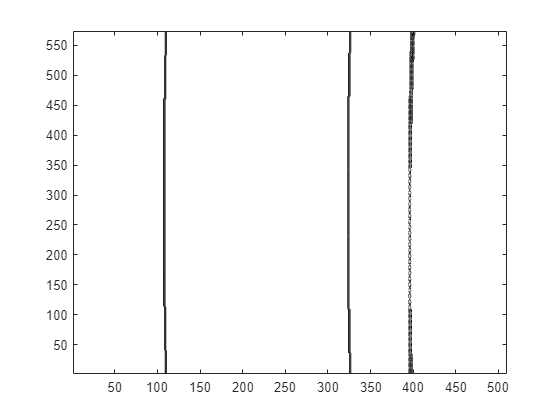

figure; colormap(gray); contour(abs(sig));


%%%===============================================================================

for i=1:Nr
    sig(:,i)=fftshift(fft(sig(:,i)));
end
disp('end of azimuth fft')

end of azimuth fft


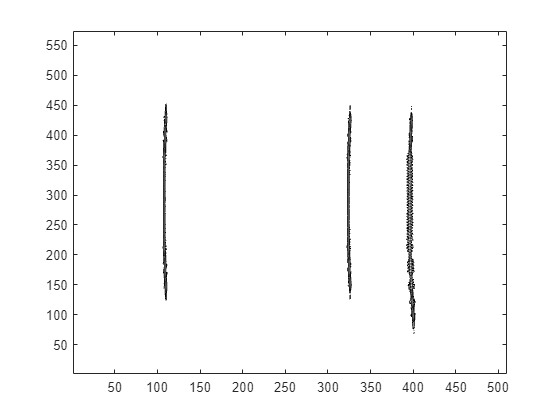


dfa=prf/Na;
fa=((0:Na-1)-Na/2)*dfa+fdc;

figure; colormap(gray); contour(abs(sig));


%% RMC with interpolation

rr=rmin+((1:Nr)-1)*bin_r;
R=8; N_ex=2000;
Up00=zeros(size(1:Nr*R+2*N_ex));
alpha_dc=1./sqrt(1-(lamda*fdc/2/va)^2);
for i=1:Na
    Up00=0*Up00;
    Up00(N_ex+1:N_ex+Nr*R)=interp(sig(i,:),R);
    alpha_fx = 1./sqrt(1-(lamda*fa(i)/2/va)^2);
    dRa=rr*(alpha_fx-alpha_dc)*sin(theta);
    kpos=R*((1:Nr)-1)+round(R*dRa/bin_r)+N_ex;
    sig(i,:)=Up00(kpos);
end
disp('end of range motion correction')

end of range motion correction


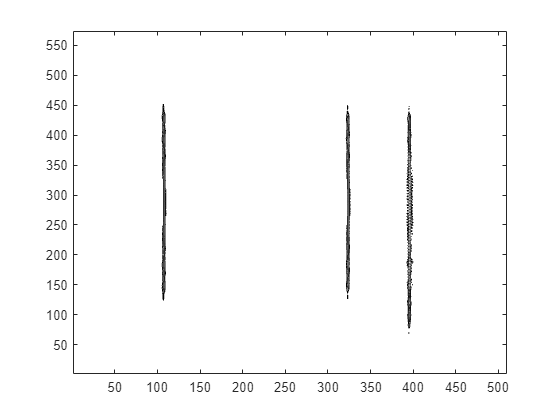

figure; colormap(gray); contour(abs(sig));


%%%===============================================================================
fa=fa-fdc; fdc=0;
beta_dc = sqrt(1-(lamda*fdc/2/va).^2);
delt_beta = sqrt(1-(lamda*fa/2/va).^2)-beta_dc;
phase2 = exp((j00*4*pi*sin(theta)/lamda)*(delt_beta'*rr));
sig = sig.*phase2;
for i=1:Nr
    sig(:,i)=ifft(fftshift(sig(:,i)));
end

disp('end of azimuth compression')

end of azimuth compression


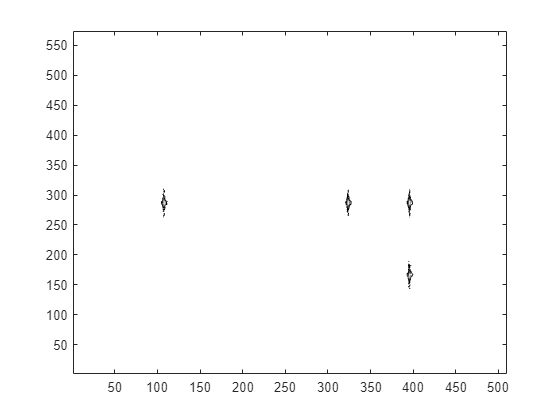

figure; colormap(gray); contour(abs(sig));